% 生成一些示例点云数据（带噪声和离群点）
points = [randn(100,2), zeros(100,1)];  % 平面上的点
points = [points; randn(10,3) * 5];  % 添加离群点

% 使用 RANSAC 进行稳健平面拟合
distanceThreshold = 0.1;
[planeModel, inlierIdx] = fitPlaneRANSAC(points, distanceThreshold);

% 显示结果
disp('平面模型:');

平面模型:


disp(planeModel);

    0.0009   -0.0723   -0.9974    0.0295



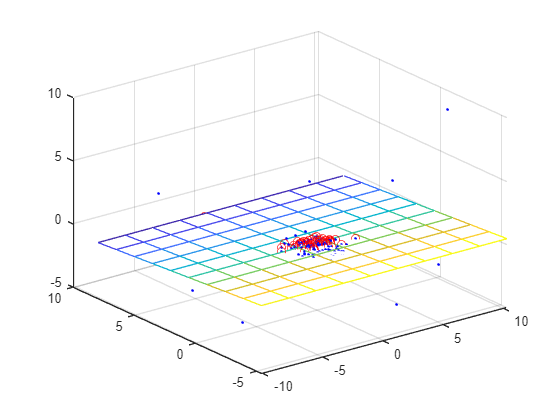


% 绘制点云和拟合平面
figure;
scatter3(points(:,1), points(:,2), points(:,3), 'b.');
hold on;
scatter3(points(inlierIdx,1), points(inlierIdx,2), points(inlierIdx,3), 'ro');

% 显示拟合平面
[X, Y] = meshgrid(linspace(min(points(:,1)), max(points(:,1)), 10), linspace(min(points(:,2)), max(points(:,2)), 10));
Z = -(planeModel(1) * X + planeModel(2) * Y + planeModel(4)) / planeModel(3);
mesh(X, Y, Z);
hold off;

function [planeModel, inlierIdx] = fitPlaneRANSAC(points, distanceThreshold)

    maxIter = 1000;  % 最大迭代次数
    numPoints = size(points, 1);  % 点的数量
    bestInlierCount = 0;  % 最优内点数量
    planeModel = [];  % 最优平面模型

    for i = 1:maxIter
        % 随机选择三个点
        sampleIdx = randperm(numPoints, 3);
        samplePoints = points(sampleIdx, :);

        % 计算平面模型
        normalVector = cross(samplePoints(2,:) - samplePoints(1,:), samplePoints(3,:) - samplePoints(1,:));
        normalVector = normalVector / norm(normalVector);
        d = -dot(normalVector, samplePoints(1,:));
        currentPlaneModel = [normalVector, d];

        % 计算每个点到平面的距离
        distances = abs(points * normalVector' + d);

        % 确定内点
        inlierIdx = find(distances < distanceThreshold);
        inlierCount = numel(inlierIdx);

        % 更新最优平面模型
        if inlierCount > bestInlierCount
            bestInlierCount = inlierCount;
            planeModel = currentPlaneModel;
        end
    end

    % 重新计算最终平面模型，使用所有内点
    if ~isempty(planeModel)
        inlierPoints = points(inlierIdx, :);
        [U, S, V] = svd(inlierPoints, 0);
        normalVector = V(:,end)';
        d = -mean(inlierPoints * normalVector');
        planeModel = [normalVector, d];
    end
end
